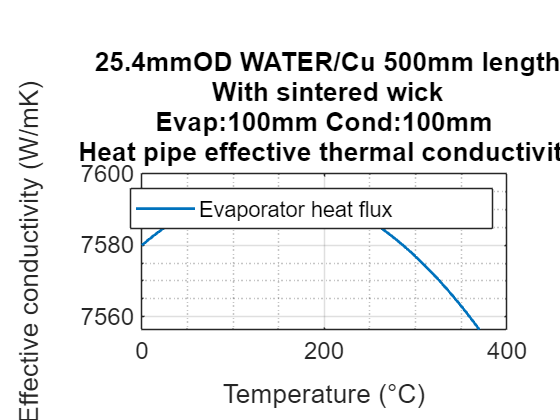

%%%%%%%%%%%%%%% Graph 5: Effective conductivity

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% Create Figure 5: Effective conductivity %%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure5 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure5);
hold(axes1,'on');

plot1 = plot(T(:,1),K_eff,'Parent',axes1);
set(plot1(1),'DisplayName','Evaporator heat flux','LineWidth',2);

ylabel({'Effective conductivity (W/mK)'});                              % Create ylabel
xlabel({'Temperature (°C)'});                        % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3,' Heat pipe effective thermal conductivity'});      

%xlim(axes1,[Tmin Tmax]);                            % X-limits of the axes
%ylim(axes1,[0 max(Qcap_90+10)]);                                  % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northeast');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')